# Jueves 11 noviembre

Capítulo 1: Introduccion a matlab

Estudiante: Victor Asanza

Materia: Simulación de Sistemas Eléctricos

Dataset: [https://ieee-dataport.org/open-access/data-server-energy-consumption-dtaset](https://ieee-dataport.org/open-access/data-server-energy-consumption-dtaset)

Frecuencia de muestreo: 4Hz

**Paso1: Cargar un archivo .mat**

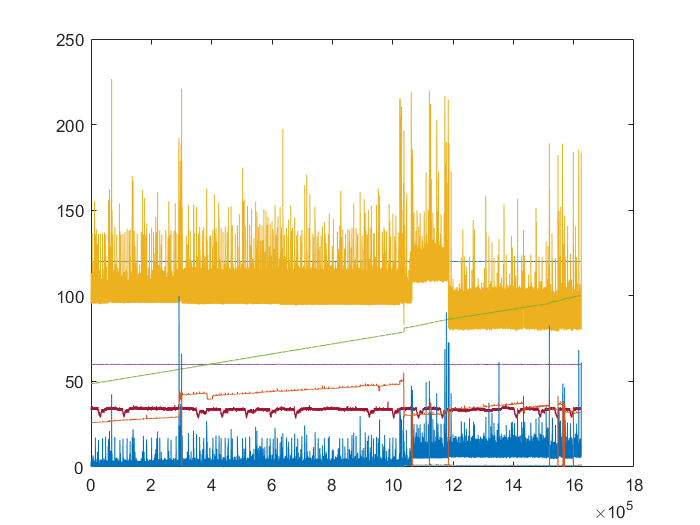

clear;clc;
path=fullfile('./dataset.mat');
data=load(path);%Load Raw Data
data=struct2cell(data);
data=data{1,1};%table
data=table2array(data(:,4:12));%array double
%Voltaje, Corriente, Potencia, Frecuencia, Energia, FP,Temp., CPU, RAM
plot(data);%datos originales

**Ejemplo 1: Cambiar la frecuencia de muestreo (4samples/seg -> 1sample/15min)**

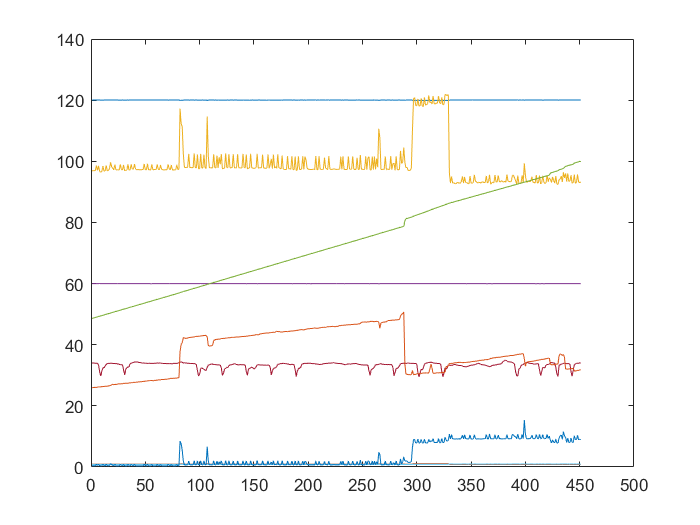

frecuencia=4;%Hz
minutos=15;%modificar la ventana temporal en minutos
ventana=frecuencia*60*minutos;%15min 3600 samples
datamean=[];datanomean=[];
for i = 1:ventana:length(data)-ventana
   datamean=[datamean;mean(data(i:i+ventana,:))];
   datanomean=[datanomean;data(i,:)];
end

plot(datamean);%datos en promedio cada 15min

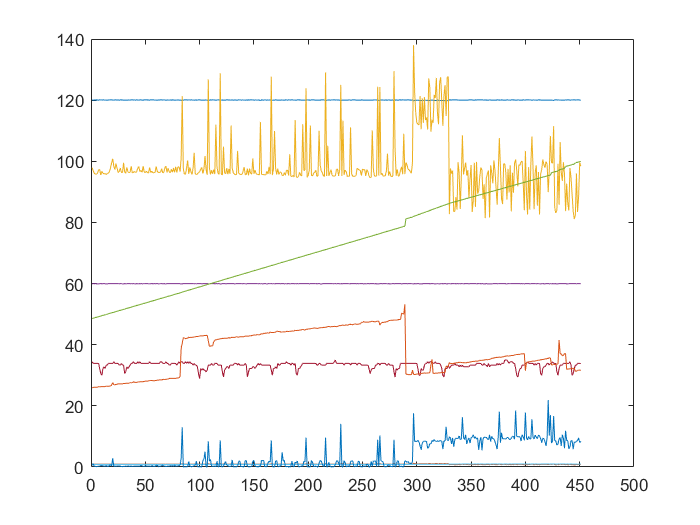

plot(datanomean);%datos SIN promedio cada 15min

#### **Ejemplo 2: Guardar un archivo .mat**

save('datamean.mat','datamean');

**Ejemplo 3: Cargar archivo con frecuencia de muestreo de 1sample / 15min**

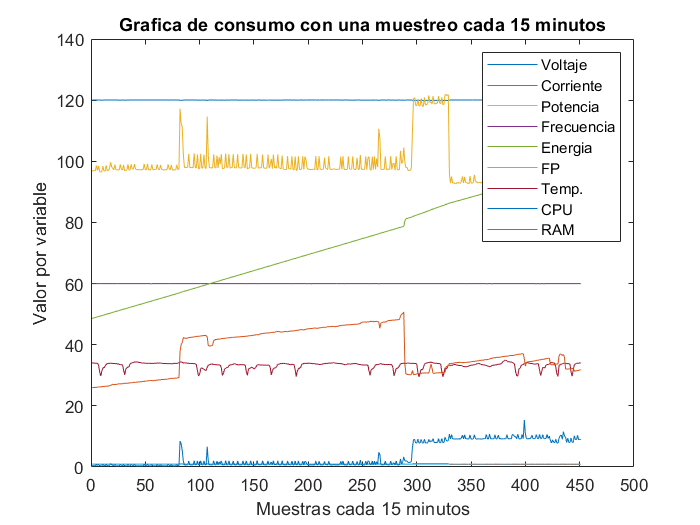

x = 1

ans = struct with fields:
       num: 451
       max: 120.0674
       min: 119.9012
      mean: 120.0236
    median: 120.0337
     range: 0.1661
       std: 0.0345


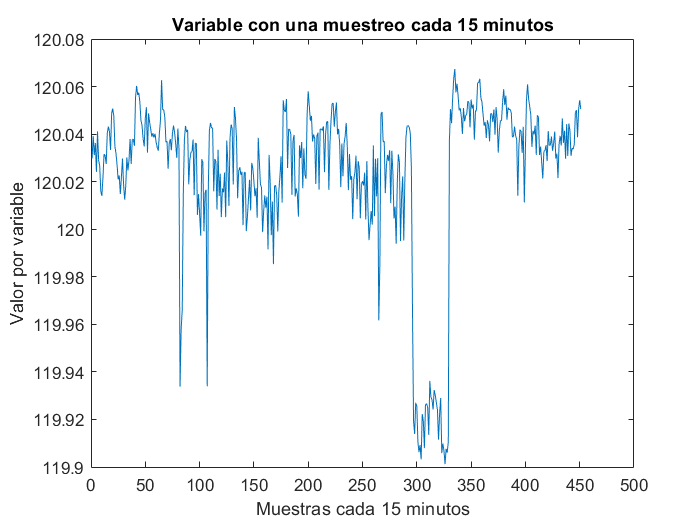

clear;%borra el worskpace
clc;%borra el comand windiw
path=fullfile('./datamean.mat');
data=load(path);
data=struct2cell(data);
data=data{1,1};%table
plot(data);%datos originales
title('Grafica de consumo con una muestreo cada 15 minutos');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP','Temp.','CPU','RAM');
xlabel('Muestras cada 15 minutos');
ylabel('Valor por variable');